# 3.6. Электромагнитное поле

Уравнения Максвелла

**I.** $\oint \mathit{\mathbf{D}}\;\mathrm{dS}=Q_f$

clear
syms rot(x) grad(x) div(x) sprod(x,y) vprod(x,y)
syms D(S) Q_f rho_f rho epsilon0
int(D,S)==Q_f

$$ans(S) = \int \text{D}\left(S\right)\mathrm{d}S=Q_{f}$$


$$\mathrm{div}\;\mathit{\mathbf{D}}=\rho_f$$


syms D E
div(D)==rho_f

$$ans = \mathrm{div}\left(\text{D}\right)=\rho_{f}$$


$$\mathrm{div}\;\mathit{\mathbf{E}}=\frac{\rho }{\varepsilon_0 }$$


div(E)==rho/epsilon0  % (в неполяризованном пространстве)

$$ans = \mathrm{div}\left(\text{E}\right)=\frac{\rho }{\epsilon_{0}}$$

$Q_f$ = полный свободный заряд внутри поверхности S

$\rho_f$ = объемная плотность заряда не в результате поляризации

**II. **$\oint \mathit{\mathbf{B}}\;\mathrm{dS}=0$

syms B(S) 
int(B,S)==0

$$ans(S) = \int B\left(S\right)\mathrm{d}S=0$$


$$\mathrm{div}\;\mathit{\mathbf{B}}=0$$


syms B
div(B)==0

$$ans = \mathrm{div}\left(B\right)=0$$

III. $\oint \mathit{\mathbf{E}}\;\mathrm{dr}=-\frac{d}{\textrm{d}t}\int \mathit{\mathbf{B}}\;\mathrm{dS}$

syms E(r) B(S,t)
int(E,r)==-diff(int(B(S,t),S),t)

$$ans(r) = \int \text{E}\left(r\right)\mathrm{d}r=-\int \frac{\partial }{\partial t}B\left(S,t\right)\mathrm{d}S$$


$$\mathrm{curl}\;\mathit{\mathbf{E}}=-\frac{\partial }{\partial t}\mathit{\mathbf{B}}$$


syms E B(t)
rot(E)==-diff(B,t)

$$ans(t) = \mathrm{rot}\left(\text{E}\right)=-\frac{\partial }{\partial t}B\left(t\right)$$

**IV.** $\oint \mathit{\mathbf{H}}\;\mathrm{dr}=I+\frac{d}{\textrm{d}t}\int \mathit{\mathbf{D}}\;\mathrm{dS}$

syms H(r) I D(S,t)
int(H,r)==I+diff(int(D(S,t),S),t)

$$ans(r) = \int H\left(r\right)\mathrm{d}r=\text{I}+\int \frac{\partial }{\partial t}\text{D}\left(S,t\right)\mathrm{d}S$$


$$\mathrm{curl}\;\mathit{\mathbf{H}}=j+\frac{\partial }{\partial t}\mathit{\mathbf{D}}$$


syms H j D(t)
rot(H)==j+diff(D,t)

$$ans(t) = \mathrm{rot}\left(H\right)=\frac{\partial }{\partial t}\text{D}\left(t\right)+j$$

$\mathrm{curl}\;\mathit{\mathbf{B}}=\mu_0 \mathit{\mathbf{j}}+\varepsilon_0 \;\mu_0 \;\frac{\partial }{\partial t}\mathit{\mathbf{E}}$   (если $\left.\mathit{\mathbf{P}}=\mathit{\mathbf{M}}=0\right)$

syms B mu0 j epsilon0 E(t)
rot(B)==mu0*j+epsilon0*mu0*diff(E,t)

$$ans(t) = \mathrm{rot}\left(B\right)=\epsilon_{0}\,\mu_{0}\,\frac{\partial }{\partial t}\text{E}\left(t\right)+j\,\mu_{0}$$

$D$ = электрическое смещение = плостность электрического потока 

#### Закон сохранения заряда


$$\oint \mathit{\mathbf{j}}\;\mathbf{dS}+\frac{\textrm{d}}{\textrm{d}t}\oint \mathit{\mathbf{D}}\;\mathbf{dS}=0$$


syms j(S) D(S,t)
int(j(S),S)+diff(int(D(S,t),S),t)==0

$$ans = \int j\left(S\right)\mathrm{d}S+\int \frac{\partial }{\partial t}\text{D}\left(S,t\right)\mathrm{d}S=0$$


$$\mathrm{div}\;\mathit{\mathbf{j}}+\frac{\partial }{\partial t}\rho =0$$


syms j rho(t)
div(j)+diff(rho)==0

$$ans(t) = \frac{\partial }{\partial t}\rho \left(t\right)+\mathrm{div}\left(j\right)=0$$

#### Плотность энергии в электрическом и магнитном полях соответственно, если epsilon и mu постоянны


$$w_e =\frac{1}{2}\mathit{\mathbf{D}}\cdot \mathit{\mathbf{E}}=\frac{1}{2}\varepsilon \;\varepsilon_0 {\;E}^2$$


syms w_e D E epsilon epsilon0 
w_e==1/2*sprod(D,E)==1/2*epsilon*epsilon0*E^2

$$ans = \left(w_{e}=\frac{\mathrm{sprod}\left(\text{D},\text{E}\right)}{2}\right)=\frac{{\text{E}}^{2}\,\epsilon \,\epsilon_{0}}{2}$$

% sprod(D,E) = D·E


$$w_m =\frac{1}{2}\mathit{\mathbf{H}}\cdot \mathit{\mathbf{B}}=\frac{1}{2}\frac{1}{\mu \;\mu_0 }B^2$$


syms w_m H B mu mu0 B
w_m==1/2*sprod(H,B)==1/2*(1/(mu*mu0))*B^2

$$ans = \left(w_{m}=\frac{\mathrm{sprod}\left(H,B\right)}{2}\right)=\frac{B^{2}}{2\,\mu \,\mu_{0}}$$

% sprod(H,B) = H·B = dot(H,B)

В частности, полная электростатическая энергия распределения зарядов


$$W=\frac{1}{2}\int D\cdot E\mathrm{dv}=\frac{1}{2}\int \rho_f V\;\mathrm{dv}$$


syms W D(v) E(v) rho_f(v) v V
W==1/2*int(sprod(D,E),v)==1/2*int(rho_f(v)*V,v)

$$ans = \left(W=\frac{\int \mathrm{sprod}\left(\text{D}\left(v\right),\text{E}\left(v\right)\right)\mathrm{d}v}{2}\right)=\frac{\int V\,\rho_{f}\left(v\right)\mathrm{d}v}{2}$$

% sprod(D,E) = D·E = dot(D,E)

Соотношение между epsilon0 и mu0

syms epsilon0 mu0 c0
epsilon0*mu0==1/c0^2

$$ans = \epsilon_{0}\,\mu_{0}=\frac{1}{{c_{0}}^{2}}$$

#### Вектор Пойтинга (плотность потока энергии)


$$\mathit{\mathbf{S}}=\mathit{\mathbf{E}}\times \mathit{\mathbf{H}}=c_0^2 \;\varepsilon_0 \;\mathit{\mathbf{E}}\times \mathit{\mathbf{B}}$$


syms S_v E H B_v c0 epsilon0 
S_v==vprod(E,H)==c0^2*epsilon0*vprod(E,B)

$$ans = \left(S_{v}=\mathrm{vprod}\left(\text{E},H\right)\right)={c_{0}}^{2}\,\epsilon_{0}\,\mathrm{vprod}\left(\text{E},B\right)$$

% vprod(E,H) = E×H

#### Эффективная глубина проникновения (скин-эффект) 

syms delta mu mu0 sigma f
delta==1/sqrt(pi*mu*mu0*sigma*f)

$$ans = \delta =\frac{1}{\sqrt{\pi }\,\sqrt{f\,\mu \,\mu_{0}\,\sigma }}$$

% sigma = удельная электропроводность

#### Векторное поле (в точке P) точечного заряда Q1, движущегося со скоростью v0


$$E=\frac{Q_1 }{4\;\pi \varepsilon_0 }\left(-\mathrm{grad}\;\frac{1}{r_1 }-\frac{1}{c_0^2 }\frac{\partial }{\partial t}\left(\frac{v_0 }{r_1 }\right)\right)=-\mathrm{grad}\;V-\frac{\partial }{\partial t}A$$


syms E Q1 epsilon0 r1 c0 v0(t) v0r1(t) d dt V A(t)
E==Q1/(4*pi*epsilon0)*(-grad(1/r1)-1/c0^2*diff(v0r1,t))==-grad(V)-diff(A,t)

$$ans(t) = \left(\text{E}=-\frac{Q_{1}\,\left(\mathrm{grad}\left(\frac{1}{r_{1}}\right)+\frac{\frac{\partial }{\partial t}{\mathrm{v0r}}_{1}\left(t\right)}{{c_{0}}^{2}}\right)}{4\,\epsilon_{0}\,\pi }\right)=-\frac{\partial }{\partial t}A\left(t\right)-\mathrm{grad}\left(V\right)$$

% v0r1(t) = v0/r1
% A(t) = магнитный векторный потенциал


$$\mathit{\mathbf{B}}=\frac{1}{c_0 }\frac{{\mathit{\mathbf{r}}}_0 }{r_0 }\mathit{\mathbf{E}}=\mathrm{curl}\;\mathit{\mathbf{A}}$$


syms B c0 r0_v r0 E A
B==1/c0*r0_v/r0*E==rot(A)

$$ans = \left(B=\frac{\text{E}\,r_{0,v}}{c_{0}\,r_{0}}\right)=\mathrm{rot}\left(A\right)$$

Скалярное поле r1

syms r1 r v0 c0 theta
r1==r*sqrt(1-v0^2/c0^2*sin(theta)^2)

$$ans = r_{1}=r\,\sqrt{1-\frac{{v_{0}}^{2}\,{\sin\left(\theta \right)}^{2}}{{c_{0}}^{2}}}$$

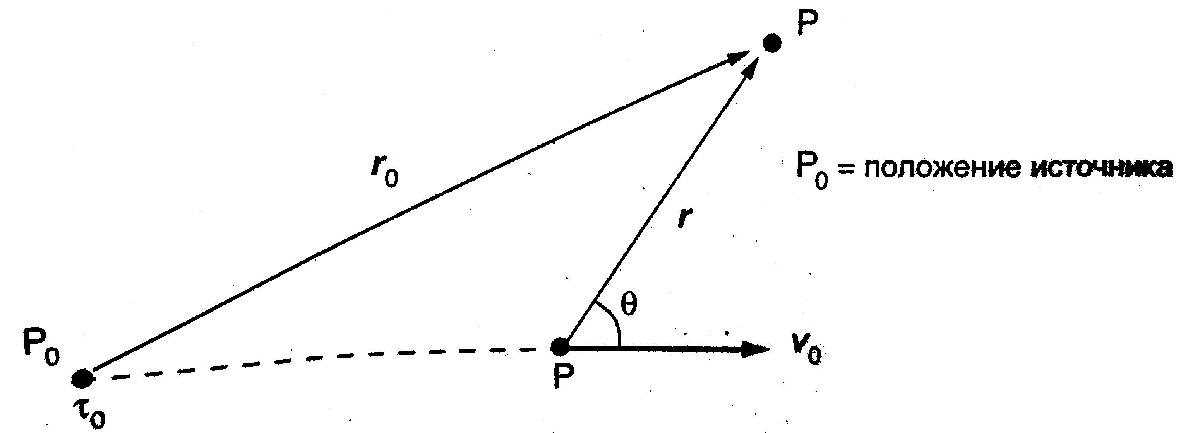

За время t частица находилась в P1

*Пример 1.* Равномерное движение


$$E=\frac{Q_1 }{4\pi \varepsilon_0 }\frac{r}{r_1^3 }\left(1-\frac{v_0^2 }{c_0^2 }\right)$$


syms E Q1 epsilon0 r_v r1 v0_v v0 c0
E==Q1/(4*pi*epsilon0)*r_v/r1^3*(1-v0^2/c0^2)

$$ans = \text{E}=-\frac{Q_{1}\,r_{v}\,\left(\frac{{v_{0}}^{2}}{{c_{0}}^{2}}-1\right)}{4\,\epsilon_{0}\,{r_{1}}^{3}\,\pi }$$


$$B=\frac{\mu_0 Q_1 }{4\;\pi }\frac{v_0 \times r}{r_1^3 }\left(1-\frac{v_0^2 }{c_0^2 }\right)$$


syms B mu0 Q1 v0 r r1 v0 c0
B==(mu0*Q1/(4*pi))*vprod(v0,r)/r1^3*(1-v0^2/c0^2)

$$ans = B=-\frac{Q_{1}\,\mu_{0}\,\left(\frac{{v_{0}}^{2}}{{c_{0}}^{2}}-1\right)\,\mathrm{vprod}\left(v_{0},r\right)}{4\,{r_{1}}^{3}\,\pi }$$

% v0crossr = v0×r

*Пример 2.* Неподвижная и квазинеподвижная частица


$$\mathit{\mathbf{E}}=\frac{Q_1 }{4\;\pi \;\varepsilon_0 }\frac{\mathit{\mathbf{r}}}{r^3 }$$


E==Q1/(4*pi*epsilon0)*r_v/r^3

$$ans = \text{E}=\frac{Q_{1}\,r_{v}}{4\,\epsilon_{0}\,r^{3}\,\pi }$$


$$\mathit{\mathbf{B}}=\frac{\mu_0 }{4\;\pi }Q_1 \frac{{\mathit{\mathbf{v}}}_0 \times \mathit{\mathbf{r}}}{r^3 }=\frac{\mu_r \varepsilon_r }{c_0^2 }{\mathit{\mathbf{v}}}_0 \times \mathit{\mathbf{E}}$$


syms mu_r epsilon_r B_v E_v v0 r E
B==mu0/(4*pi)*Q1*vprod(v0,r)/r^3==mu_r*epsilon_r/c0^2*vprod(v0,E)

$$ans = \left(B=\frac{Q_{1}\,\mu_{0}\,\mathrm{vprod}\left(v_{0},r\right)}{4\,r^{3}\,\pi }\right)=\frac{\epsilon_{r}\,\mu_{r}\,\mathrm{vprod}\left(v_{0},\text{E}\right)}{{c_{0}}^{2}}$$

% vprod(v0,r) = v0×r
% vprod(v0,E) = v0×E

#### Соотношение между временем поля t и временем источника tau

syms tau t r c0
tau==t-r/c0

$$ans = \tau =t-\frac{r}{c_{0}}$$